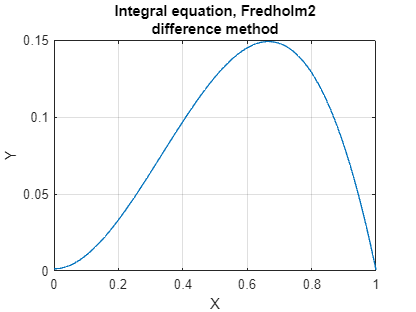

addpath(genpath('./'));


% test case
lambda = 12;
a = 0; b = 1;
n = 101;
core = @(x, t)(1/(x + 1));
rightFunc = @(x)(x^2*(1 - x) - 1/(x + 1));

[X, Y] = differenceSolverFredholm2( ...
    lambda, core, a, b, rightFunc, n, @getSimpsonWeights ...
    );

title = [
    "Integral equation, Fredholm2", 
    "difference method"
];
complexPlot(X, Y, title);

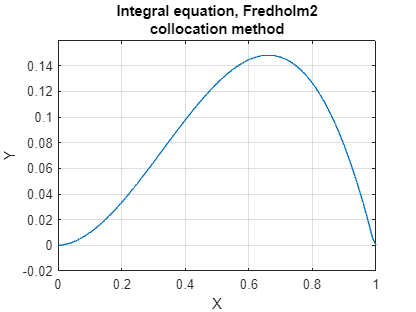


% ============================================
lambda = 12;
a = 0; b = 1;
n = 101;
core = @(x, t)(1/(x + 1));
rightFunc = @(x)(x^2*(1 - x) - 1/(x + 1));

[X, Y] = collocationSolverFredholm2( ...
    lambda, core, a, b, rightFunc, n, @getSimpsonWeights ...
    );

title = [
    "Integral equation, Fredholm2", 
    "collocation method"
];
complexPlot(X, Y, title);

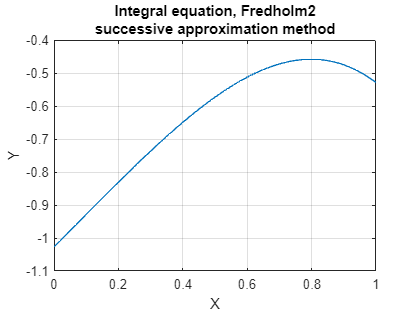


% ============================================

lambda = 1;
a = 0; b = 1;
n = 101;
core = @(x, t)(sin(x + 1) / 20);
rightFunc = @(x)(x^2*(1 - x) - 1/(x + 1));

[X, Y] = successiveApproximationSolver( ...
    lambda, core, a, b, rightFunc, n, @getSimpsonWeights, 10^(-6) ...
    );

title = [
    "Integral equation, Fredholm2", 
    "successive approximation method"
];
complexPlot(X, Y, title);



% ============================================
%lambda = 12;
%a = 0; b = 1;
%n = 101;
%core = @(x, t)(1/(x + 1));
%rightFunc = @(x)(x^2*(1 - x) - 1/(x + 1));

%[X, Y] = coreSubstitutionSolver( ...
%    lambda, core, a, b, rightFunc, n, @getSimpsonWeights ...
%    );


%plot(X, Y);

% ============================================
